# Satellite Example

clc 
clear all

s = zpk('s');
sample_time = 1e-3;

G = ss(0.036*(s+25.28)/(s^2*(s^2+0.0396*s+1)));
Gd = c2d(G,sample_time);
systemnames='Gd';

% inputvar='[d;n;r;u]';
% outputvar='[Gd+d-r;u;r-n-d-Gd]';
inputvar='[r;u]';
outputvar='[Gd - r;r-Gd]';
input_to_Gd='[u]';
P=sysic;

K = ss(7.9212*(s+0.1818)*(s^2-0.2244*s+0.8981)/((s^2+3.899*s+4.745)*(s^2+1.039*s+3.395)));
Kd = c2d(K,sample_time);
%Kd = hinfsyn(P, 1, 1);
P_star_K=ss(lft(P,Kd));
isstable(P_star_K)

ans = logical
   1


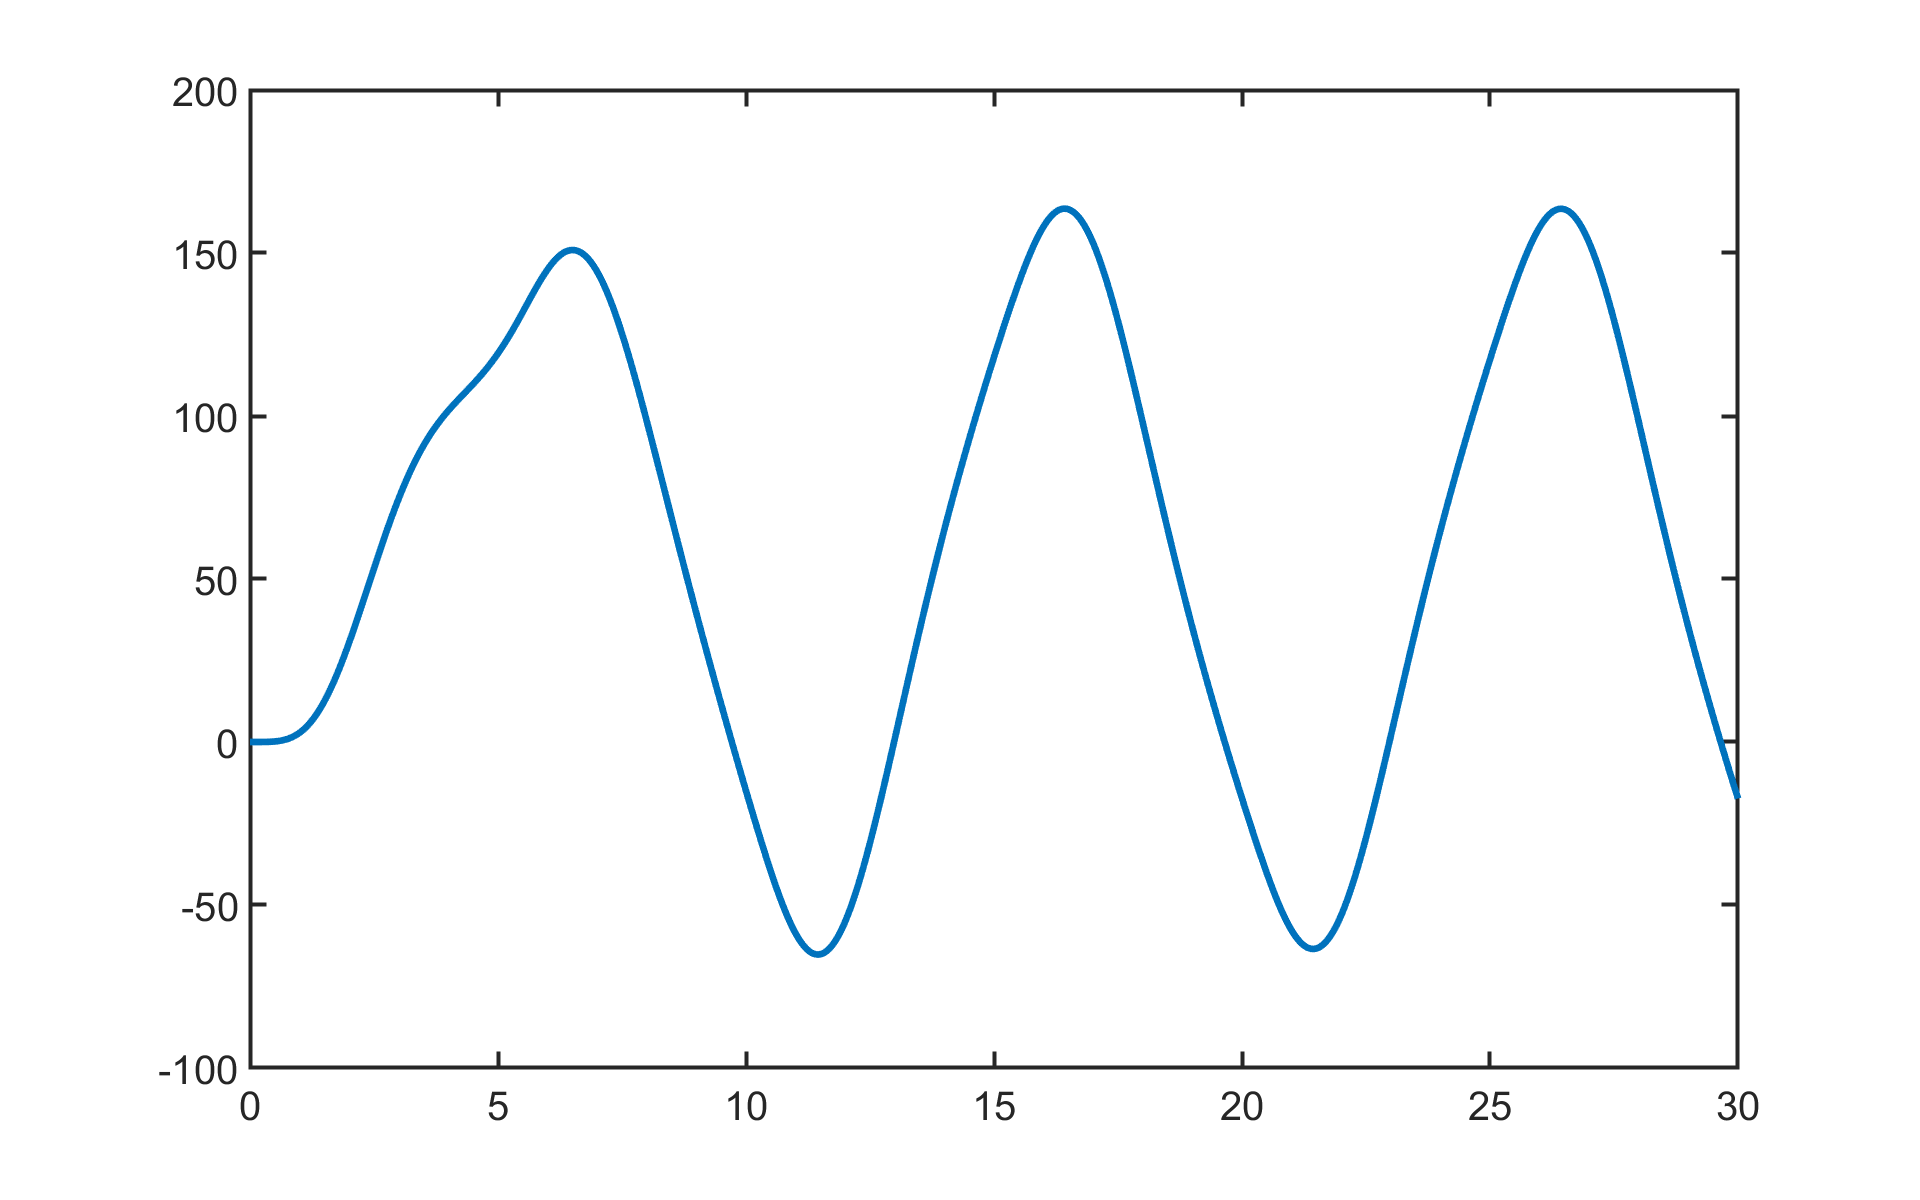

addpath('models&livescripts')
ampl = 100;
simulation = sim('myModel','SimulationMode','normal');
data_satellite = simulation.get('data_satellite');
u = simulation.get('u');
time = data_satellite.Time(:,1);
tracking_val = data_satellite.Data(:,1);
ouput_val = data_satellite.Data(:,2);


u = u.Data(:,1);
x = simulation.xout{1}.Values.Data;

plot(time,ouput_val);


[A,B,C,D] = ssdata(P_star_K); 


## SDA


N = 0;
iteration_number = 0;
Nmax = length(u) - 1;
u_inf = [];
e_inf = [];
y_inf = [];
impr = [];
act_trValue = [];
tic
colNb = 1;
plots = {};
plots{1} = [];
plots{2} = [];
plots{3} = [];
plots{4} = [];
plots{5} = [];
while N < Nmax
    
    count = 100;
   
    N = N + count;
    
    
    x0 = x(N-count+1, :)';
    
    %l-input m-output system; in supervector description l*(N+1) - input
    %m*(N+1)-output
    l = length(B(1,:));
    m = length(C(:,1));
    u0 = u(N - count + 1:N+1, :);
    
    [G, d] = get_G(A,B, C, D, x0, count);

    
    R = eye(l*(count+1));
    Q = eye(m*(count+1));
    
    beta = .25;
    r = tracking_val(N - count + 1:N+1, :);
    do_plot = 0;
    do_print = 0;
    [u_inf1, e_inf1, y_inf1, impr1, iteration_number1] = SDA(G,d, beta,r, u0,1,1, do_plot);
    u_inf = [u_inf; u_inf1{length(u_inf1)}];
    y_inf = [y_inf; y_inf1{length(y_inf1)}];
    e_inf = [e_inf; e_inf1{length(e_inf1)}];
    act_trValue = [act_trValue; r];
    impr = [impr; impr1];
    iteration_number = iteration_number + iteration_number1;
    if mod(N, 1e5)==0
    fprintf('Iteration %d of %d\n', N+1, Nmax);
    end
    q = length(u_inf1);
    for t = 1:5
            plots{t} = [plots{t}; y_inf1{t}];
    end
end 
ell_time = toc;


%Plots
figure
hold on

len = length(time);


%All
% plot(time(1:len),tracking_val(1:len), 'DisplayName', 'tracking value');
% plot(time(1:len),ouput_val(1:len),'DisplayName', 'k = 0');
% 
% for t = 1:5
%     plot(time(1:len), plots{t}(1:len), 'DisplayName', ['k = ',num2str(t*5)]);
% end

%First, tracking value, last
plot(time(1:len),act_trValue(1:len), 'DisplayName', 'tracking value');
plot(time(1:len),ouput_val(1:len),'DisplayName', 'k = 0');
plot(time(1:len), plots{1}(1:len), 'DisplayName', ['SDA k = ',num2str(5)]);
plot(time(1:len), plots{4}(1:len), '--', 'DisplayName', ['SDA k = ',num2str(20)]);



legend();
fprintf('TOTAL TIME: %f', ell_time);

TOTAL TIME: 2.644851

fprintf('TOTAL ITERATION NUMBER: %d', iteration_number);

TOTAL ITERATION NUMBER: 11049

fprintf('AVERGAGE IMPROVEMENT: %f', sum(impr)/length(impr));

AVERGAGE IMPROVEMENT: 164401398249.571869

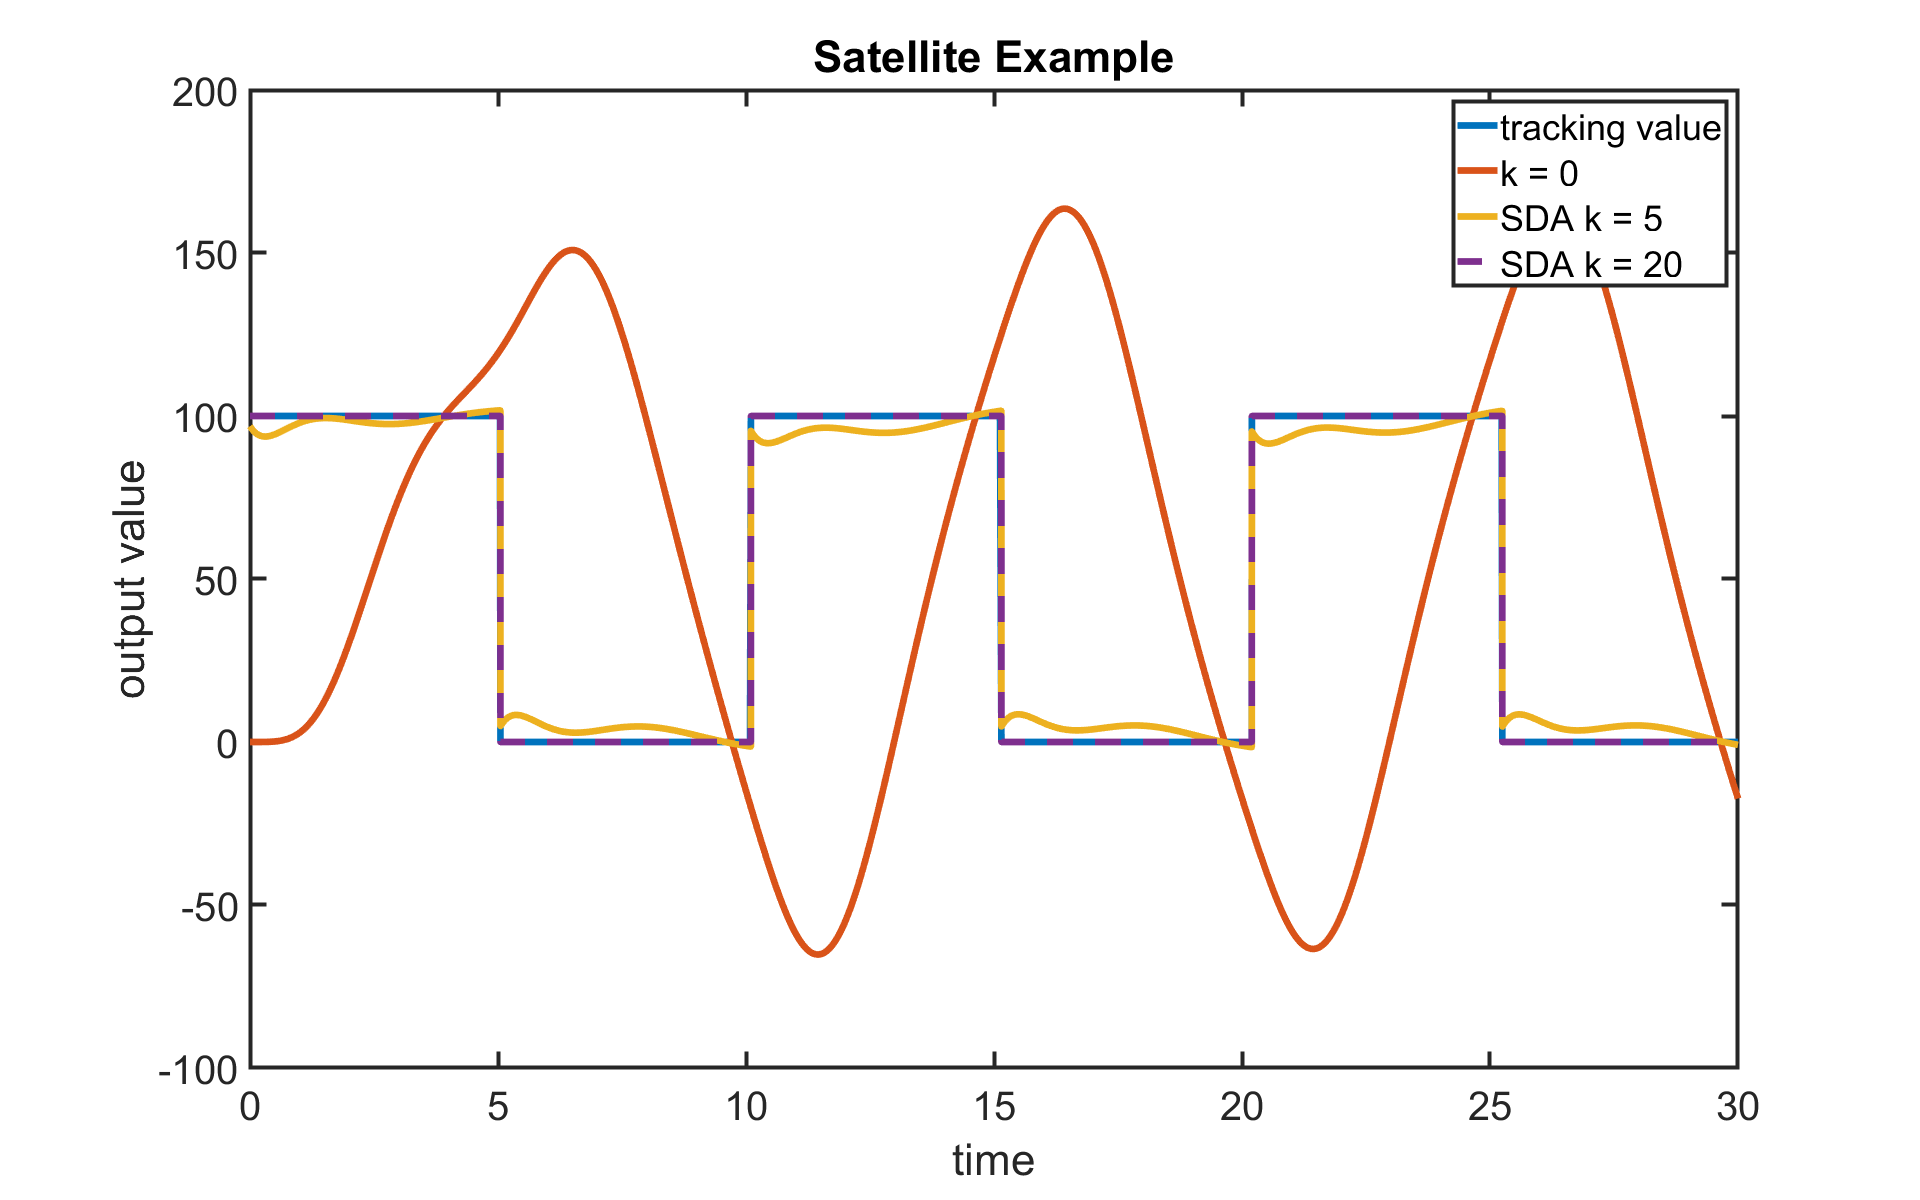

%ylim([-.8 1.7])
xlabel('time')
ylabel('output value')
title('Satellite Example')



hold off

## SDA

N = 0;
iteration_number = 0;
Nmax = length(u) - 1;
u_inf = [];
e_inf = [];
y_inf = [];
impr = [];
act_trValue = [];
tic
colNb = 1;
plots = {};
plots{1} = [];
plots{2} = [];
plots{3} = [];
plots{4} = [];
plots{5} = [];
while N < Nmax
    
    count = 100;
   
    N = N + count;
    
    
    x0 = x(N-count+1, :)';
    
    %l-input m-output system; in supervector description l*(N+1) - input
    %m*(N+1)-output
    l = length(B(1,:));
    m = length(C(:,1));
    u0 = u(N - count + 1:N+1, :);
    
    [G, d] = get_G(A,B, C, D, x0, count);

    
    R = eye(l*(count+1));
    Q = eye(m*(count+1));
    
    beta = .25;
    r = tracking_val(N - count + 1:N+1, :);
    do_plot = 0;
    do_print = 0;
    [u_inf1, e_inf1, y_inf1, impr1, iteration_number1, error_history] = SDA(G,d, beta,r, u0, R, Q,do_plot);
    u_inf = [u_inf; u_inf1{length(u_inf1)}];
    y_inf = [y_inf; y_inf1{length(y_inf1)}];
    e_inf = [e_inf; e_inf1{length(e_inf1)}];
    act_trValue = [act_trValue; r];
    impr = [impr; impr1];
    iteration_number = iteration_number + iteration_number1;
    if mod(N, 1e5)==0
    fprintf('Iteration %d of %d\n', N+1, Nmax);
    end
    q = length(plots);
    for t = 1:q
            plots{t} = [plots{t}; y_inf1{t}];
    end
end 
ell_time = toc;


hold on

len = length(time);



%First, tracking value, last
plot(time(1:len), plots{2}(1:len), 'DisplayName', 'SDA k = 10');
plot(time(1:len), plots{4}(1:len), 'DisplayName', 'SDA k = 20');



legend();
fprintf('TOTAL TIME: %f', ell_time);

TOTAL TIME: 2.644851

fprintf('TOTAL ITERATION NUMBER: %d', iteration_number);

TOTAL ITERATION NUMBER: 11049

fprintf('AVERGAGE IMPROVEMENT: %f', sum(impr)/length(impr));

AVERGAGE IMPROVEMENT: 164401398249.571869

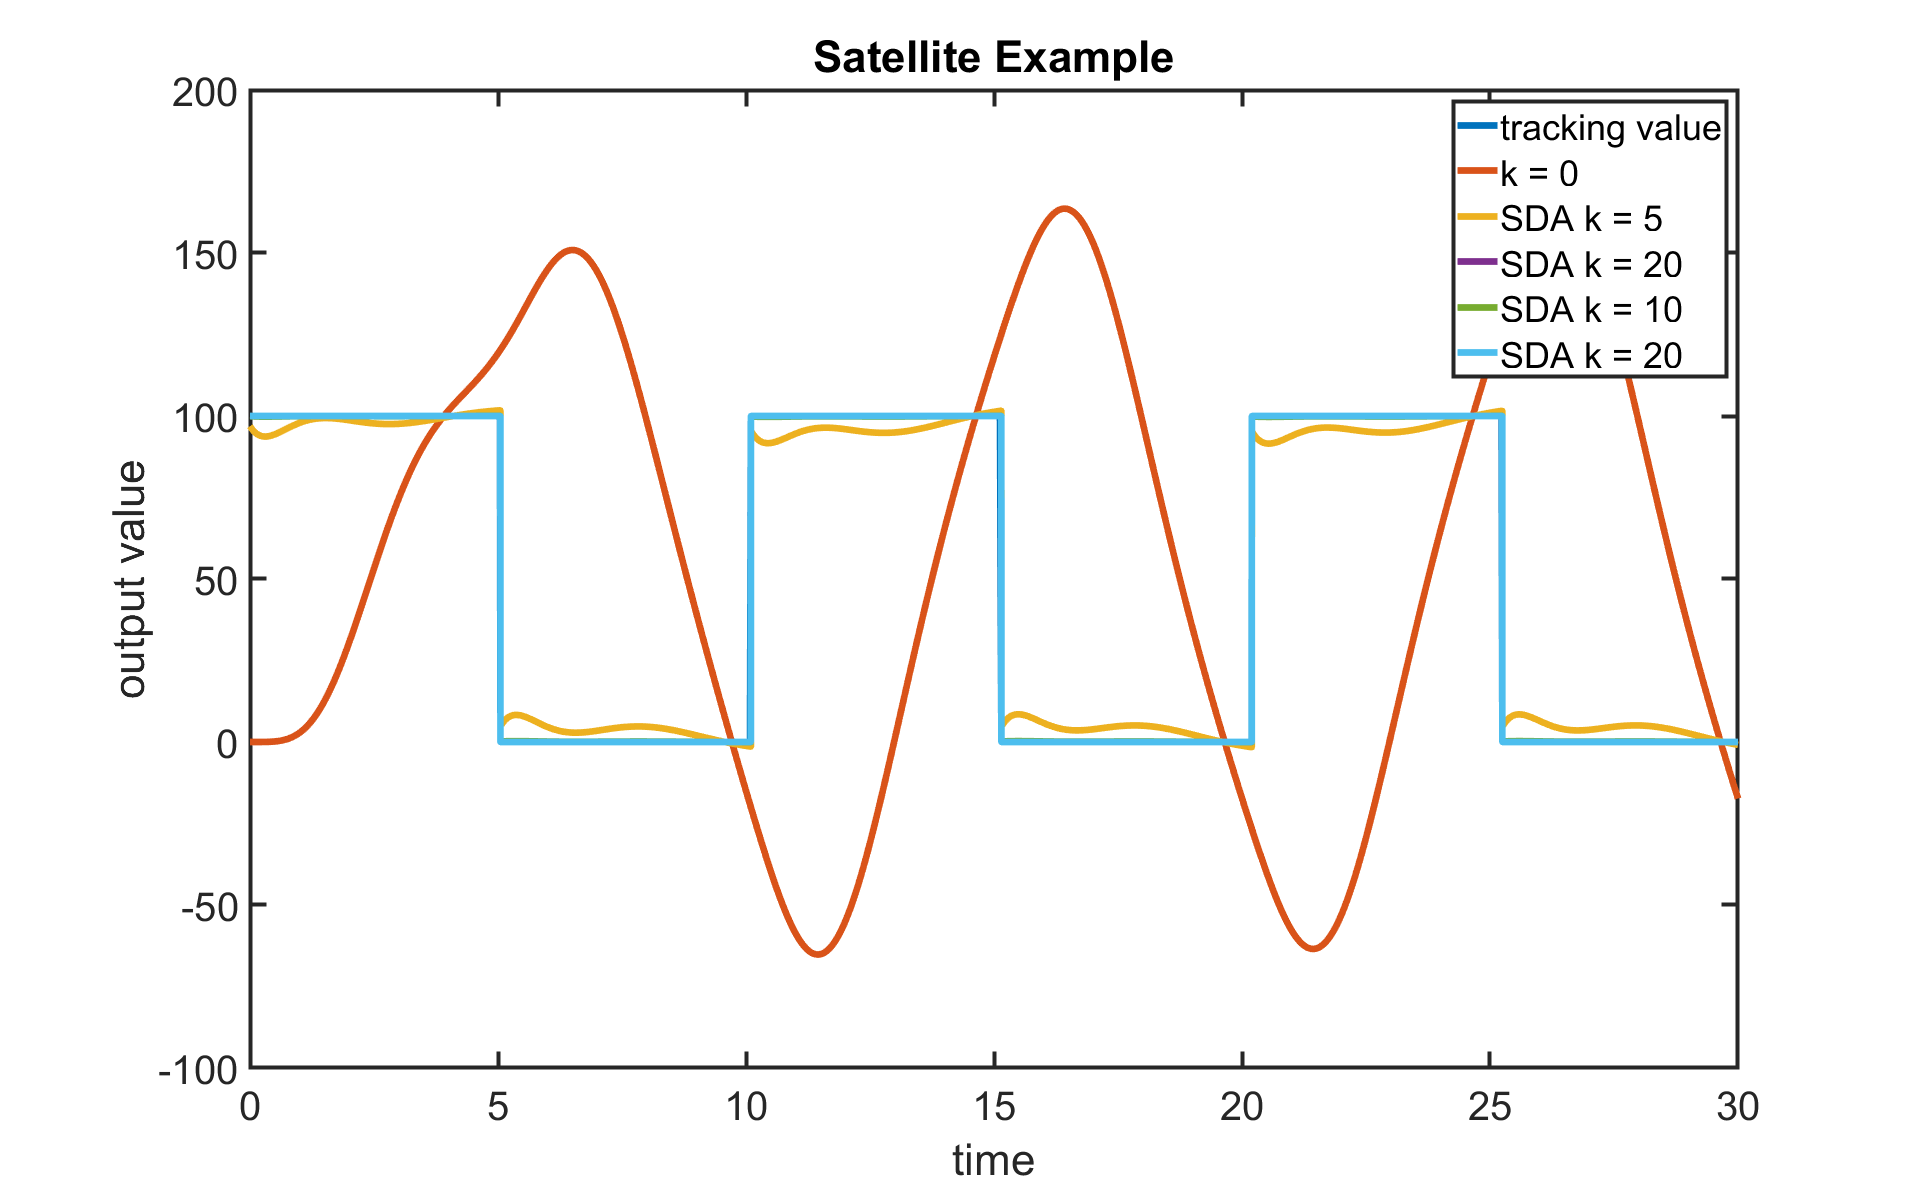

%ylim([-.8 1.7])
xlabel('time')
ylabel('output value')
title('Satellite Example')



hold off